clear all
clc
% Inicialización del entorno de trabajo: se eliminan todas las variables anteriores y se limpia la consola.

% Toolbox de Robótica de Peter Corke: se define la matriz homogénea identidad que representa el marco base (S0).
H0 = SE3();  % Matriz identidad (base)

% Definición de transformaciones relativas entre marcos consecutivos.
% Cada transformación incluye una rotación (sobre X, Y o Z) y una traslación asociada.

H1 = SE3(rotx(-pi/2), [0 0 0]);        % Rotación de -90° en X sin traslación.
H2 = SE3(roty(pi/2), [0 0 0]);         % Rotación de 90° en Y sin traslación.
H3 = SE3(rotz(pi/2), [0 -5 0]);        % Rotación de 90° en Z y traslación -5 en Y.
H4 = SE3(rotx(0),     [-5 0 0]);       % Sin rotación, traslación de -5 en X.
H5 = SE3(rotx(pi/2),  [0 0 5]);        % Rotación de 90° en X y traslación de 5 en Z.

% Cálculo de transformaciones homogéneas acumuladas desde el marco base hasta el efector final.
H0_1 = H0 * H1;
H1_2 = H0_1 * H2;
H2_3 = H1_2 * H3;
H3_4 = H2_3 * H4;
H4_5 = H3_4 * H5;

% Extracción de la posición (vector de traslación) de cada marco a partir de su transformación homogénea.
p0 = transl(H0);
p1 = transl(H0_1);
p2 = transl(H1_2);
p3 = transl(H2_3);
p4 = transl(H3_4);
p5 = transl(H4_5);

% Se agrupan las coordenadas X, Y, Z de todos los marcos para visualizar la estructura del robot.
X = [p0(1) p1(1) p2(1) p3(1) p4(1) p5(1)];
Y = [p0(2) p1(2) p2(2) p3(2) p4(2) p5(2)];
Z = [p0(3) p1(3) p2(3) p3(3) p4(3) p5(3)];

% Se genera una gráfica 3D que muestra la trayectoria estructural del brazo robótico.
plot3(X, Y, Z, '-o', 'LineWidth', 2, 'MarkerSize', 6);
axis([-6 2 -10 2 -1 6]); grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Robot graficado');
hold on;

% Visualización de los marcos de coordenadas asociados a cada punto de la estructura.
trplot(H0,    'rgb', 'frame', 'S0', 'length', 0.5);
trplot(H0_1,  'rgb', 'frame', 'S1', 'length', 0.5);
trplot(H1_2,  'rgb', 'frame', 'S2', 'length', 0.5);
trplot(H2_3,  'rgb', 'frame', 'S3', 'length', 0.5);
trplot(H3_4,  'rgb', 'frame', 'S4', 'length', 0.5);
trplot(H4_5,  'rgb', 'frame', 'S5', 'length', 0.5);

% Se imprime en consola la transformación homogénea final desde el marco base hasta el marco S5.
disp('Transformación  H4_5:');

Transformación  H4_5:


disp(H4_5);

      0.9992  -0.02664   0.02815    -4.859
     0.02665    0.9996-5.646e-07    -4.994
    -0.02814 0.0007509    0.9996     5.274
           0         0         0         1


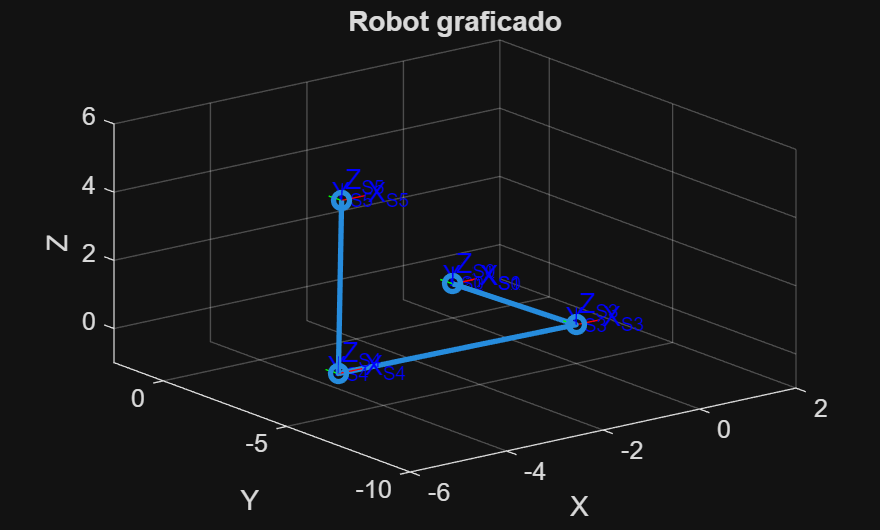

hold off;